## Main2.m

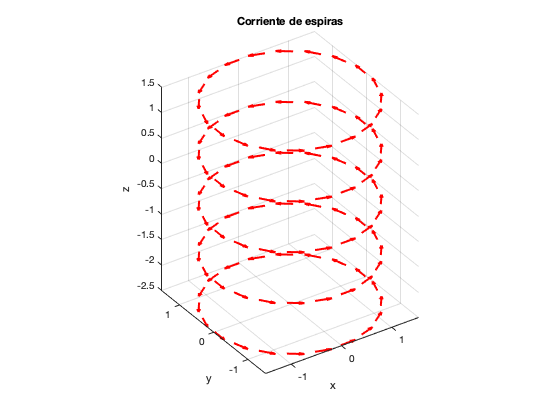

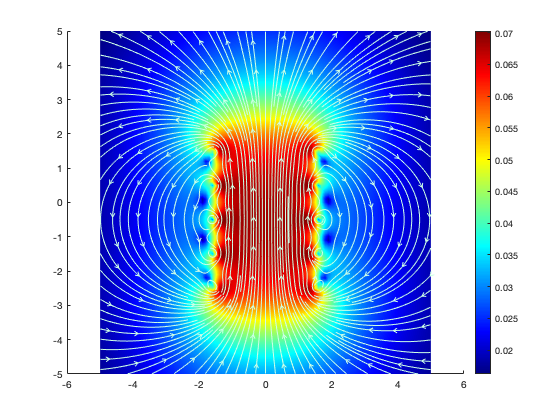

clear all
close all
clf
clc
% -------------------- PARTE 1: GRAFICACIÓN DE LAS ESPIRAS --------------------
nl = 5;               % Número de espiras que componen la bobina
N = 20;               % Puntos por espira usados para discretizar cada espira
R = 1.5;              % Radio de cada espira (m)
sz = 1;               % Separación entre espiras (altura entre cada una) (m) (paso en Z)
I = 300;              % Corriente eléctrica que circula por las espiras (A)
mo = 4*pi*1e-7;       % Permeabilidad magnética del (H/m)
km = mo * I / (4*pi); % Constante de Biot–Savart
rw = 0.2;             % Grosor efectivo del alambre (radio efectivo del alambre, usado para evitar singularidades)
ds = 0.1;             % Resolución para graficación de campo (más grande = más rápido)

% Generación de la geometría de las espiras y los elementos de corriente
[Px, Py, Pz, dx, dy, dz] = Espiras(nl, N, R, sz);

% -------------------- PARTE 2: VISUALIZACIÓN DEL CAMPO MAGNÉTICO --------------------
plot_option = true;  % Solo para graficar el campo (sin devolver z)
CampoB(ds, km, Px, Py, Pz, dx, dy, nl, N, rw, plot_option);


% -------------------- PARTE 3: SIMULACIÓN DE LA TRAYECTORIA --------------------
% % Aquí se calculará el gradiente del campo Bz para simular el movimiento
% del dipolo (calculamos Bz y z para usarlos en la simulación)
plot_option = false;
ds = 0.005;  % Resolución más fina para el cálculo del gradiente

[Bz, z] = CampoB(ds, km, Px, Py, Pz, dx, dy, nl, N, rw, plot_option);

% Parámetros del dipolo magnético
mag = 1000;     % Magnitud del momento magnético (A·m²)
m = 0.009;      % Masa (kg)
zo = 4.9;       % Posición inicial (m)
dt = 0.05;      % Paso de tiempo (s)
vz = 0.7;       % Velocidad inicial (m/s)
gamma = 0.08;   % Coeficiente de fricción (kg/s)

% Ejecutar la simulación
% Simular la trayectoria del dipolo magnético
zm = Trayectoria(Bz, z, mag, m, zo, dt, vz, gamma);

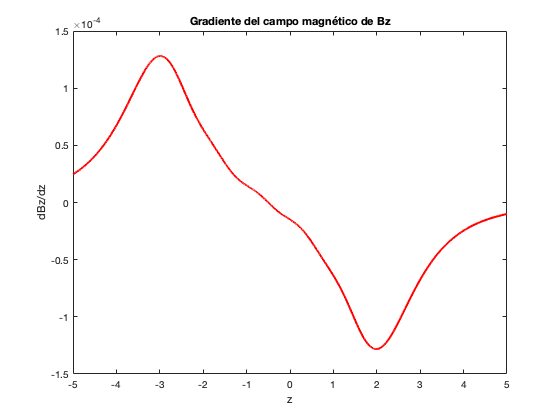

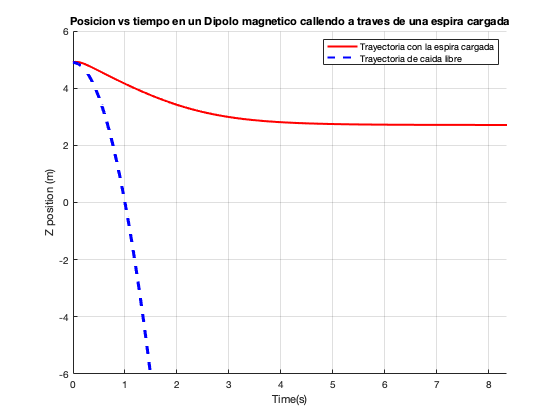

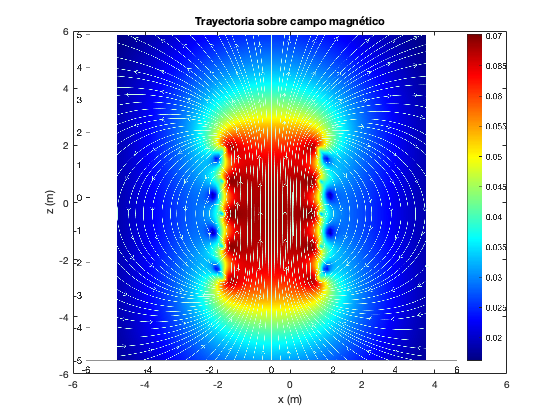

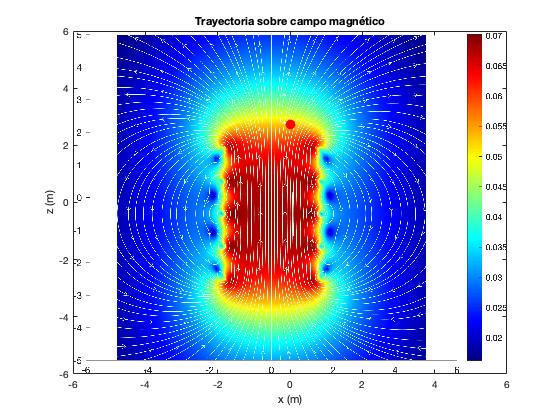

    "Video guardado como "    "animacion_resultante"




% Crear animación con imagen de fondo
nombre_video="animacion_resultante";
imagen="campo_magnetico.png";
animation(zm, imagen,nombre_video);



% ---------------------------------------------------------------------------------------
% ----------------------------- FUNCIONES DEL PROGRAMA ----------------------------------
% ---------------------------------------------------------------------------------------

% Función Espiras

function [Px,Py,Pz,dx,dy,dz] = Espiras(nl,N,R,sz)
% Esta función genera la geometría de las espiras y los vectores tangentes
    % a cada elemento de corriente, necesarios para aplicar la ley de Biot–Savart.
    
    dtheta = 2*pi/N; % Paso angular para discretizar la espira (ángulo entre puntos consecutivos)
    ang = 0:dtheta:(2*pi-dtheta); % Vector de ángulos para ubicar los puntos de la espira
    sz=1; % Espaciado entre espiras (sobrescribe el valor de entrada, hay que tener cuidado con esto)
    s=1; % Índice inicial para rellenar los vectores
    
    for i = 1:nl
    % Posición de los puntos de la espira i-ésima
    Px(s:s+N-1) = R*cos(ang); % Coordenadas x de los puntos de la espira
    Py(s:s+N-1) = R*sin(ang); % Coordenadas y de los puntos de la espira
    Pz(s:s+N-1) = -nl/2*sz+(i-1)*sz; % Centrado alrededor de z=0
    
    % Vectores diferenciales de corriente (producto cruz en Biot–Savart)
    dx(s:s+N-1) = -Py(s:s+N-1)*dtheta; % Componente x del vector tangente (dirección de corriente)
    dy(s:s+N-1) = Px(s:s+N-1)*dtheta; % Componente y del vector tangente
    
    s=s+N; % Actualiza el índice para la siguiente espira
    
    end
    
    dz = zeros(1, N*nl); % Sin componente z, corriente en plano XY
    
    % Visualización 3D de las espiras y las direcciones de corriente
    figure(1)
    quiver3(Px,Py,Pz,dx,dy,dz,0.5,'-r','LineWidth',2) % Flechas que representan los elementos de corriente
    view(-34,33)  % Ángulo de vista en 3D
    xlabel('x'); ylabel('y');zlabel('z')  % Etiquetas de ejes
    title('Corriente de espiras') % Título del gráfico
    axis equal % Escalado igual en todos los ejes
    
end


% Función Campo Mangético

function [Bz,z] = CampoB(ds,km,Px, Py, Pz, dx, dy, nl, N, rw, plot_option)
% Esta función calcula el campo magnético generado por las espiras
    % usando la Ley de Biot–Savart:
    % dB = (μ₀/4π) * (I dL × r̂) / r²
    % donde r̂ es el vector unitario entre el elemento de corriente y el punto
    
    x = -5:ds:5; y = x; z = x; % Define la malla de puntos para el cálculo del campo
    
    if plot_option
        % Si se va a graficar, se usa una malla 3D cúbica
        x=z;
        y=z;
    else
        % Si no se grafica, se usa una región más pequeña centrada en el eje z
        x=-0.1:0.01:0.1;
        y=-0.1:0.01:0.1;
    end

    Lx = length(x); Ly = length(y); Lz = length(z); % Longitudes de cada dimensión del grid
    dBx = zeros(Lx, Ly, Lz,'single'); % Inicializa componente x del campo
    dBy = dBx; % Inicializa componente y del campo
    dBz = dBx; % Inicializa componente z del campo
    
    % Ciclos para recorrer todos los puntos del espacio
    for i = 1:Lx
        for j = 1:Ly
            for k = 1:Lz
                for l = 1:nl*N
                    % Vector desde el alambre (elemento de corriente) hasta
                    % el punto de observación
                    rx = x(i)-Px(l);
                    ry = y(j)-Py(l);
                    rz = z(k)-Pz(l);
                    
                    r = sqrt(rx^2+ry^2+rz^2+rw^2); % Distancia regularizada (evita singularidad)
                    r3 = r^3;  % Cubo de la distancia
                    
                    % Componentes del campo usando Biot–Savart (solo se usa componente transversal)
                    dBx(i,j,k) = dBx(i,j,k)+km*dy(l)*rz/r3;
                    dBy(i,j,k) = dBy(i,j,k)+km*dx(l)*rz/r3;
                    dBz(i,j,k) = dBz(i,j,k)+km*(dx(l)*ry-dy(l)*rx)/r3;
    
                end
            end
        end
    end
    
   if plot_option 
       
        %Convertir a plano XZ (visualización)
        Bmag = sqrt(dBx.^2+dBy.^2+dBz.^2); % Magnitud del campo total
        centery = round(Ly/2); % Índice del plano medio en y
        Bx_xz = squeeze(dBx(:,centery,:)); % Proyección del campo en x (plano XZ)
        Bz_xz = squeeze(dBz(:,centery,:)); % Proyección del campo en z (plano XZ)
        Bxz = squeeze(Bmag(:,centery,:)); % Magnitud total del campo en plano XZ
        
        %Graficar
        figure(2);
        hold on;
        pcolor(x,y,(Bxz').^(1/3)); shading interp; colormap jet; colorbar;
        h1 = streamslice(x,z,Bx_xz',Bz_xz',3); % Líneas de corriente del campo
        set(h1,'Color',[0.8 1 0.9]);
        exportgraphics(figure(2) , 'campo_magnetico.png','Resolution', 300);
        Bz=1; % Valor de retorno ficticio (no se usa en modo gráfico)
   else
       % Extraer Bz en el eje z para usar en la simulación de trayectoria
        idx_x = ceil(Lx/2); % Índice del centro en x
        idx_y = ceil(Ly/2); % Índice del centro en y
        Bz = squeeze(dBz(idx_x, idx_y,:)); % Bz en eje z

        % Calcular el gradiente de Bz respecto a z (dBz/dz)
        dBz_dz_profile = diff(Bz)./diff(z); % Aproximación numérica de derivada
        z_mid=z(1:end-1) + diff(z)/2; % Puntos medios entre muestras de z
        
        %Graficar
        figure
        plot(z_mid,dBz_dz_profile, 'r-','LineWidth',2)
        xlabel('z'); ylabel('dBz/dz')
        title('Gradiente del campo magnético de Bz')
   end
end

% Función Trayectoria

function zm = Trayectoria(Bz,z,mag,m,zo,dt,vz,gamma)
    % Simula el movimiento de un dipolo magnético en un campo no uniforme.
    % Se usa la fuerza magnética F = ∇(m·B) ≈ m·(dBz/dz) si m está alineado con z.
    % Se incluye fricción proporcional a la velocidad.
    % Considera peso, fuerza magnética y fricción viscosa.
    
    w=-m*9.81; % Fuerza peso (negativa porque apunta hacia abajo)
    zm(1)=zo; % Posición inicial del dipolo (con campo magnético)
    zmfree(1)=zo; % Posición inicial de comparación (caída libre)
    vz(1)=0.7; % Velocidad inicial del dipolo en z
    vzfree(1)=0; % Velocidad inicial de caída libre (sin campo)
    tt(1)=0; % Tiempo inicial
    cc =1; % Contador de iteraciones
    
   while zm(cc) > -3 % Detener simulación si cae por debajo de z = -3
        delta = 0.005; % Pequeño incremento para derivada numérica
        Bz_forward = interp1(z, Bz, zm(cc) + delta, 'linear', 'extrap');
        Bz_backward = interp1(z, Bz, zm(cc) - delta, 'linear', 'extrap');
        dBz_dz = (Bz_forward - Bz_backward) / (2 * delta); % Derivada centrada
    
        Fm(cc) = -mag * dBz_dz; % Fuerza magnética (atrae hacia menor B si m y B están alineados)
        Ff = -gamma * vz(cc); % Fuerza de fricción (lineal con la velocidad)
        F(cc) = Fm(cc) + w + Ff; % Fuerza total: magnética + peso + fricción
        a = F(cc) / m; % Aceleración resultante por la 2ª ley de Newton
    
        zm(cc+1) = zm(cc) + vz(cc)*dt + 0.5*a*dt^2; % Posición siguiente (con campo)
        vz(cc+1) = vz(cc) + a*dt; % Velocidad siguiente (con campo)
        
        % Simulación de caída libre sin campo, solo gravedad
        zmfree(cc+1) = zmfree(cc) + vzfree(cc)*dt + 0.5*(-9.81)*dt^2;
        vzfree(cc+1) = vzfree(cc) + (-9.81)*dt;
        
        % Reemplazo de integración con paso de Runge–Kutta 4 para mayor precisión
        z_axis=z;
        [zm(cc+1),vz(cc+1)]=rk4_step(zm(cc), vz(cc), dt, @(z,v) a_func(z,v, Bz, z_axis, mag, gamma, m));

        tt(cc+1) = tt(cc) + dt; % Tiempo siguiente
        
        % Condición de paro si la velocidad se aproxima a cero
        if abs(vz(cc)) < 1e-3
            break
        end
        
        cc = cc + 1;
        
    end


    figure(99)
    hold on
    plot(tt,zm, 'r-', 'LineWidth',2) % Trayectoria con campo magnético
    plot(tt,zmfree,'b--','LineWidth',2) % Trayectoria de caída libre

    grid on 
    xlabel('Time(s)')
    ylabel('Z position (m)')
    title(' Posicion vs tiempo en un Dipolo magnetico callendo a traves de una espira cargada ')
    legend('Trayectoria con la espira cargada', 'Trayectoria de caida libre','Southwest')
    axis([0 max(tt) -6 6])
    

end

%Función aceleración

% Esta función calcula la aceleración de un dipolo magnético en caída vertical,
% bajo la influencia de: 
%  - un campo magnético no uniforme Bz(z),
%  - la gravedad,
%  - y una fuerza de fricción viscosa proporcional a la velocidad.

function a=a_func(z, v, Bz, z_axis, mag, gamma, m)
    
    %Computacional: define un pequeño desplazamiento para estimar la derivada de Bz por diferencias finitas.
    %Físico: se necesita calcular la pendiente dBz/dz en la posición actual.
    delta=0.005;
    
    % Computacional: usa interpolación lineal para estimar el valor del campo magnético Bz en los puntos cercanos a la posición actual z±δ.
    % Físico: se aproxima la variación del campo Bz alrededor de la posición actual del dipolo.
    Bz_forward=interp1(z_axis,Bz, z + delta, 'linear','extrap');
    Bz_backward=interp1(z_axis,Bz, z - delta, 'linear','extrap');
    % Computacional: calcula la derivada de Bz respecto a z usando diferencia centrada.
    % Físico: esto es necesario para determinar la fuerza magnética sobre un dipolo alineado con el eje z.
    dbz_dz=(Bz_forward-Bz_backward)/(2*delta);
    
    % Físico: fuerza magnética sobre un dipolo en un campo no uniforme: Aquí, se asume que el momento magnético está alineado con el eje z, y el signo negativo implica atracción hacia zonas de menor campo.
    Fm=-mag*dbz_dz; 
    % Físico: fuerza de fricción viscosa, que se opone al movimiento y es proporcional a la velocidad. Este modelo representa pérdida de energía por interacción con un medio (como aire).
    Ff=-gamma*v; % fuerza de fricción
    % Físico: suma de todas las fuerzas que actúan sobre el dipolo: Fm: magnética, Ff: fricción, −mg: peso (negativo, hacia abajo)
    F=Fm+Ff- m*9.81; % fuerza total
    % Físico: es la aceleración instantánea del dipolo, incluyendo todas las fuerzas mencionadas.
    a=F/m; % aceleración, esta es calculada por medio de la segunda Ley de Newton
end


% Función Runge Kutta

function [z_next, v_next]=rk4_step(z,v,dt, a_total)
% Esta función implementa un paso del método de Runge-Kutta 4º orden (RK4)
% para integrar numéricamente las ecuaciones de movimiento:
% dz/dt = v
% dv/dt = a_total(z, v)
% donde a_total es una función que calcula la aceleración neta (por fuerzas magnéticas, fricción y gravedad).

    %k1
    k1z=v;
    k1v=a_total(z,v);

    %k2
    k2z=v +(dt/2)*k1v;
    k2v=a_total(z+(dt/2)*k1z,v+(dt/2)*k1v);

    %k3
    k3z=v+(dt/2)*k2v;
    k3v=a_total(z+(dt/2)*k2z,v+(dt/2)*k2v);

    %k4
    k4z=v+dt*k3v;
    k4v=a_total(z+(dt*k3z),v+(dt*k3v));
    
    % Nueva posición z: combinación ponderada de las pendientes, donde los puntos intermedios tienen doble peso.
    % Físico: representa una mejor aproximación al área bajo la curva v(t) es decir, el desplazamiento.
    z_next= z + (dt/6)*(k1z+2*k2z+2*k3z+k4z);
    
    % Nueva velocidad v: integración del cambio de velocidad por la aceleración neta.
    v_next= v + (dt/6)*(k1v+2*k2v+2*k3v+k4v);
end

% Animación con Imágen de Fondo

function animation(zm, imagen, nombre_video)
    % zm: vector con posiciones del objeto
    % imagen: nombre del archivo de imagen de fondo (png)
    % nombre_video: nombre del video de salida (mp4)

    % Rango físico que usaste para graficar tu imagen
    x_range = [-6, 6];
    z_range = [-6, 6];

    % Crear objeto de video
    writerObj = VideoWriter(nombre_video, 'MPEG-4'); 
    writerObj.FrameRate = 30; % Puedes bajarlo para hacer la animación más lenta
    open(writerObj);

    % Cargar imagen
    img = imread(imagen);

    figure(100); clf;
    imagesc(x_range, z_range, flipud(img)); % Imagen de fondo
    axis xy;
    hold on;
    xlabel('x (m)');
    ylabel('z (m)');
    title('Trayectoria sobre campo magnético');

    % Simular trayectoria punto a punto
    for i = 1:length(zm)
        cla;
        imagesc(x_range, z_range, flipud(img)); % Redibujar fondo
        axis xy;
        hold on;
        scatter(0, zm(i), 100, 'r', 'filled');
        xlim(x_range);
        ylim(z_range);
        frame = getframe(gcf);
        writeVideo(writerObj, frame);
    end

    close(writerObj);
    disp(['Video guardado como ', nombre_video]);
end
